# Analysis of data aided synchronization viability

## 1024 bytes CLTU

clear all;
close all;



tic;

dB_min = 0;
dB_max = 20;




EbN0_dB = dB_min:dB_max;
EbN0 = 10.^(EbN0_dB/10);
N_eb = size(EbN0,2);

L0 = 12:1024*4+44;
L = 1024*4+44;
N_L0 = size(L0,2);
m = zeros(N_eb,N_L0);
s = zeros(N_eb,N_L0);
ser = zeros(N_eb,N_L0);

for k=1:N_eb
    for l=1:N_L0
        [m(k,l), s(k,l)] = mcrb_phase_distrib_analytical(EbN0(1,k),L0(1,l),L,0);
        ser(k,l) = 2* qpsk_theoretical_ber_rp(EbN0(1,k),m(k,l),s(k,l));
    end
end

'qpsk_theoretical_ber_rp' is not found in the current folder or on the MATLAB path, but exists in:
    D:\DataNew\Universidad\TFG\code\tfg-receiver-algorithms-for-satellite-systems\MATLAB\utils\qpsk_utilities

Change the MATLAB current folder or add its folder to the MATLAB path.


save("data_aided_analysis_1.mat")

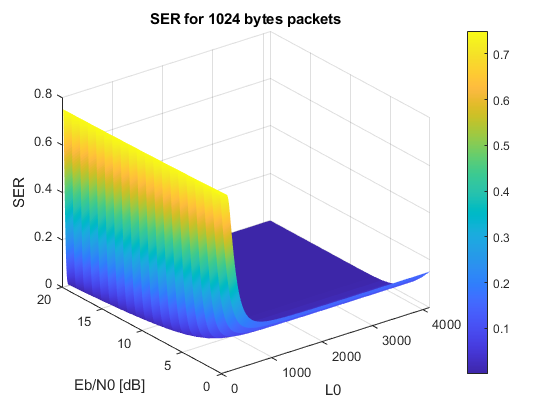

load("data_aided_analysis_1.mat")
ser_at_0db = ser(1,:);
ser_at_3db = ser(4,:);
ser_at_7db = ser(8,:);
ser_at_10db = ser(11,:);
ser_at_13db = ser(14,:);
ser_at_17db = ser(18,:);
ser_at_19db = ser(20,:);

figure;
surf(L0,EbN0_dB,ser,'LineStyle','none');
xlabel("L0")
ylabel("Eb/N0 [dB]")
zlabel("SER");
%view(0,90)
title("SER for 1024 bytes packets")
colorbar

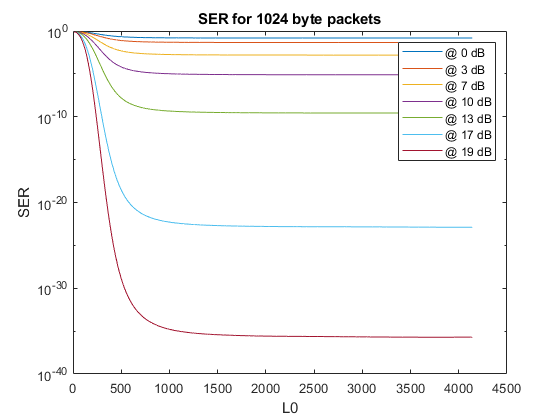

figure;
semilogy(L0,ser_at_0db);
hold on;
semilogy(L0,ser_at_3db);
semilogy(L0,ser_at_7db);
semilogy(L0,ser_at_10db);
semilogy(L0,ser_at_13db);
semilogy(L0,ser_at_17db);
semilogy(L0,ser_at_19db);
xlabel("L0");
ylabel("SER");
title("SER for 1024 byte packets");
legend("@ 0 dB", ......
       "@ 3 dB", ...
       "@ 7 dB", ...
       "@ 10 dB", ...
       "@ 13 dB", ...
       "@ 17 dB", ...
       "@ 19 dB");

## 512 bytes CLTU

clear all;
close all;



tic;

dB_min = 0;
dB_max = 20;




EbN0_dB = dB_min:dB_max;
EbN0 = 10.^(EbN0_dB/10);
N_eb = size(EbN0,2);

L0 = 12:1024*4+44;
L = 512*4+44;
N_L0 = size(L0,2);
m = zeros(N_eb,N_L0);
s = zeros(N_eb,N_L0);
ser = zeros(N_eb,N_L0);

for k=1:N_eb
    for l=1:N_L0
        [m(k,l), s(k,l)] = mcrb_phase_distrib_analytical(EbN0(1,k),L0(1,l),L,0);
        ser(k,l) = 2* qpsk_theoretical_ber_rp(EbN0(1,k),m(k,l),s(k,l));
    end
end

save("data_aided_analysis_2.mat")

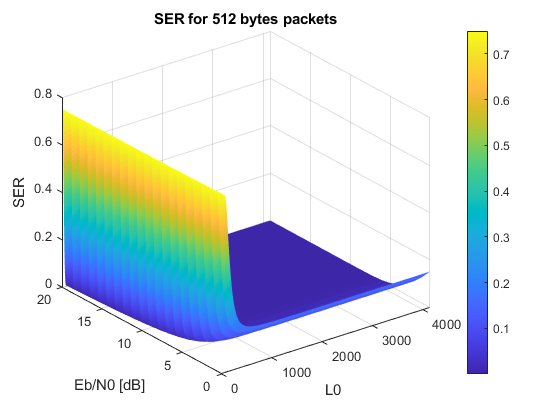

load("data_aided_analysis_2.mat")
ser_at_0db = ser(1,:);
ser_at_3db = ser(4,:);
ser_at_7db = ser(8,:);
ser_at_10db = ser(11,:);
ser_at_13db = ser(14,:);
ser_at_17db = ser(18,:);
ser_at_19db = ser(20,:);

figure;
surf(L0,EbN0_dB,ser,'LineStyle','none');
xlabel("L0")
ylabel("Eb/N0 [dB]")
zlabel("SER");
%view(0,90)
title("SER for 512 bytes packets")
colorbar

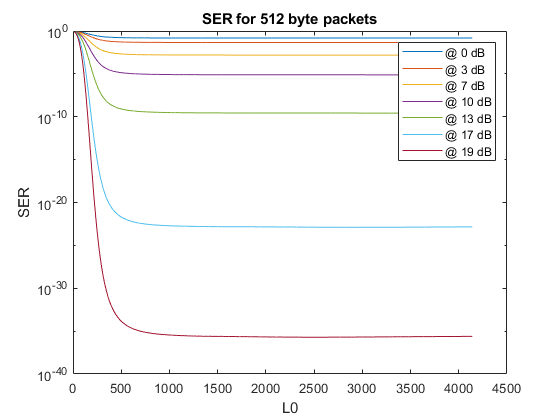

figure;
semilogy(L0,ser_at_0db);
hold on;
semilogy(L0,ser_at_3db);
semilogy(L0,ser_at_7db);
semilogy(L0,ser_at_10db);
semilogy(L0,ser_at_13db);
semilogy(L0,ser_at_17db);
semilogy(L0,ser_at_19db);
xlabel("L0");
ylabel("SER");
title("SER for 512 byte packets");
legend("@ 0 dB", ......
       "@ 3 dB", ...
       "@ 7 dB", ...
       "@ 10 dB", ...
       "@ 13 dB", ...
       "@ 17 dB", ...
       "@ 19 dB");

## 256 bytes CLTU

clear all;
close all;



tic;

dB_min = 0;
dB_max = 20;




EbN0_dB = dB_min:dB_max;
EbN0 = 10.^(EbN0_dB/10);
N_eb = size(EbN0,2);

L0 = 12:1024*4+44;
L = 256*4+44;
N_L0 = size(L0,2);
m = zeros(N_eb,N_L0);
s = zeros(N_eb,N_L0);
ser = zeros(N_eb,N_L0);

for k=1:N_eb
    for l=1:N_L0
        [m(k,l), s(k,l)] = mcrb_phase_distrib_analytical(EbN0(1,k),L0(1,l),L,0);
        ser(k,l) = 2* qpsk_theoretical_ber_rp(EbN0(1,k),m(k,l),s(k,l));
    end
end

save("data_aided_analysis_3.mat")

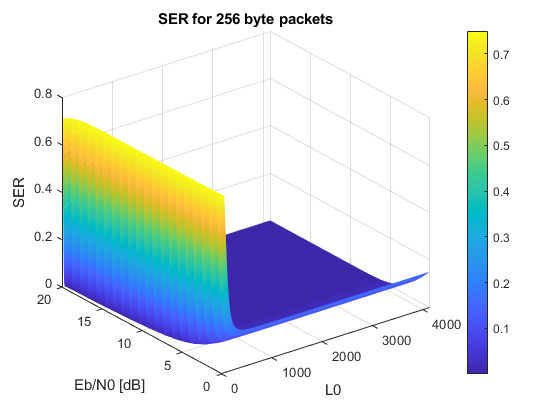

load("data_aided_analysis_3.mat")
ser_at_0db = ser(1,:);
ser_at_3db = ser(4,:);
ser_at_7db = ser(8,:);
ser_at_10db = ser(11,:);
ser_at_13db = ser(14,:);
ser_at_17db = ser(18,:);
ser_at_19db = ser(20,:);

figure;
surf(L0,EbN0_dB,ser,'LineStyle','none');
xlabel("L0")
ylabel("Eb/N0 [dB]")
zlabel("SER");
%view(0,90)
title("SER for 256 byte packets")
colorbar

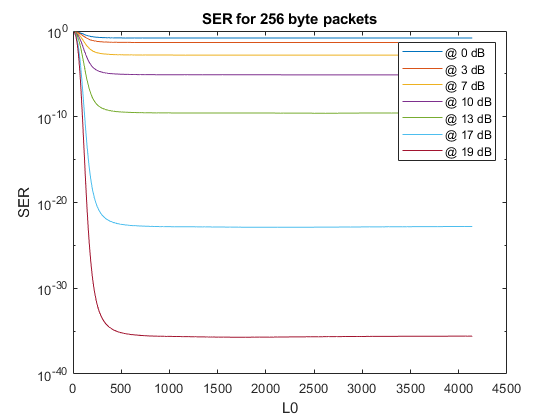

figure;
semilogy(L0,ser_at_0db);
hold on;
semilogy(L0,ser_at_3db);
semilogy(L0,ser_at_7db);
semilogy(L0,ser_at_10db);
semilogy(L0,ser_at_13db);
semilogy(L0,ser_at_17db);
semilogy(L0,ser_at_19db);
xlabel("L0");
ylabel("SER");
title("SER for 256 byte packets");
legend("@ 0 dB", ......
       "@ 3 dB", ...
       "@ 7 dB", ...
       "@ 10 dB", ...
       "@ 13 dB", ...
       "@ 17 dB", ...
       "@ 19 dB");

## 128 bytes CLTU

clear all;
close all;



tic;

dB_min = 0;
dB_max = 20;




EbN0_dB = dB_min:dB_max;
EbN0 = 10.^(EbN0_dB/10);
N_eb = size(EbN0,2);

L0 = 12:1024*4+44;
L = 128*4+44;
N_L0 = size(L0,2);
m = zeros(N_eb,N_L0);
s = zeros(N_eb,N_L0);
ser = zeros(N_eb,N_L0);

for k=1:N_eb
    for l=1:N_L0
        [m(k,l), s(k,l)] = mcrb_phase_distrib_analytical(EbN0(1,k),L0(1,l),L,0);
        ser(k,l) = 2* qpsk_theoretical_ber_rp(EbN0(1,k),m(k,l),s(k,l));
    end
end

save("data_aided_analysis_4.mat")

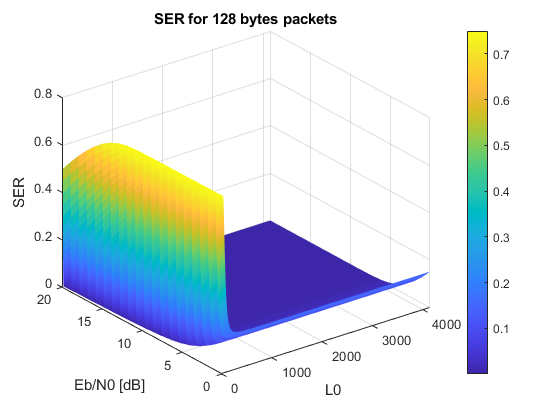

load("data_aided_analysis_4.mat")
ser_at_0db = ser(1,:);
ser_at_3db = ser(4,:);
ser_at_7db = ser(8,:);
ser_at_10db = ser(11,:);
ser_at_13db = ser(14,:);
ser_at_17db = ser(18,:);
ser_at_19db = ser(20,:);

figure;
surf(L0,EbN0_dB,ser,'LineStyle','none');
xlabel("L0")
ylabel("Eb/N0 [dB]")
zlabel("SER");
%view(0,90)
title("SER for 128 bytes packets")
colorbar

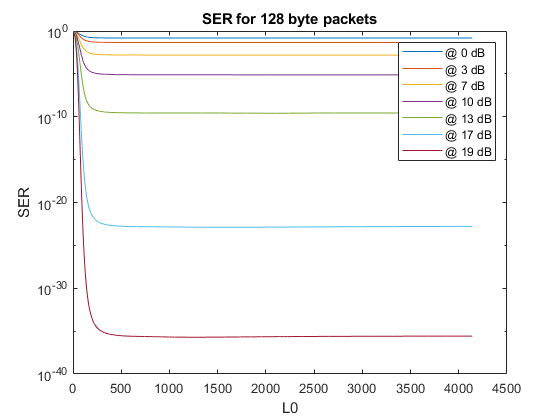

figure;
semilogy(L0,ser_at_0db);
hold on;
semilogy(L0,ser_at_3db);
semilogy(L0,ser_at_7db);
semilogy(L0,ser_at_10db);
semilogy(L0,ser_at_13db);
semilogy(L0,ser_at_17db);
semilogy(L0,ser_at_19db);
xlabel("L0");
ylabel("SER");
title("SER for 128 byte packets");
legend("@ 0 dB", ......
       "@ 3 dB", ...
       "@ 7 dB", ...
       "@ 10 dB", ...
       "@ 13 dB", ...
       "@ 17 dB", ...
       "@ 19 dB");

## Needed symbols for the first block

TODO. This section was supposed to be used for calculating the number of needed symbols to estimate the carrier for the demodulation of the first BCH codeblock.